## 2 DOF Flexible Joint Robot Manipulator

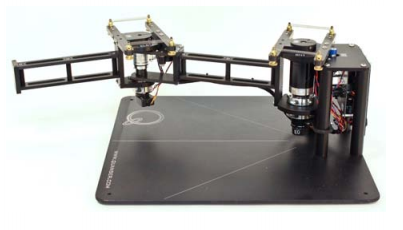

### Parameters

- Li: lengQ of link i (i=1,2)

- Lci: distance to centre of centre of gravity of link i (i=1,2)

- mi: mass i (i=1,2)

- Ii: moment of inertia at z axis of link i (i=1,2)

- Iri: moment of inertia at z axis of rotor i (i=1,2)

- ksi: torsional stiffness of spring i (i=1,2)

- Bi: viscous damping coefficient of link (i=1,2)

- Bmi: viscous damping coefficient of motor (i=1,2)

- qi: angular position of link (i=1,2)

- phii: angular position of motor (i=1,2)

### Parameters Value

- L1 = 0.343 m (User Manual)

- L2 = 0.267 m (User Manual)

- Lc1 = 0.2 m (Veltman Thesis)                         0.1590 m (Electrical School) **??

- Lc2 = 0.25 m (Veltman Thesis)                       0.0550 m (Electrical School) **??

- m1 = 0.5 kg (Veltman Thesis)                         1.51 kg (Electrical School) **??

- m2 = 1 kg (Veltman Thesis)                            0.87326 kg (Electrical School) **??

- l1 = 0.01 kgm^2 (Veltman Thesis)                   0.0392 kgm^2 (Electrical School) ** (check which one to take)

- l2 = 0.01 kgm^2 (Veltman Thesis)                   0.0081 kgm^2 (Electrical School) ** (check which one to take)

- B1 = 0.070364 Nms/rad (Electrical School)    0.038 Nms/rad (Veltman Thesis) **

- B2 = 0.028211 Nms/rad (Electrical School)    0.03 Nms/rad (Veltman Thesis) **

- Bm1 = 8.435 Nms/rad (Veltman Thesis)        4.5 Nms/rad (Electrical School) **

- Bm2 = 0.136 Nms/rad (Veltman Thesis)        0.5 Nms/rad (Electrical School) **

- Ks1 = 9 Nm/rad (Veltman Thesis)                  9 Nm/rad (Electrical School)

- Ks2 = 4 Nm/rad (Veltman Thesis)                  4 Nm/rad (Electrical School)  

- Ir1 = 0.217 kgm^2 (Veltman Thesis)              0.0628 kgm^2 (Electrical School) ** (check which one to take)

- Ir2 = 0.007 kgm^2 (Veltman Thesis)              0.0026 kgm^2 (Electrical School)  **(check which one to take)

clear;
syms L1 L2 Lc1 Lc2 m1 m2 I1 I2 Ir1 Ir2 B1 B2 Ks1 Ks2 Bm1 Bm2 q1(t) q2(t) phi1(t) phi2(t)
syms Q1 Q2 Q1D Q2D Q1DD Q2DD PHI1 PHI1D PHI1DD PHI2 PHI2D PHI2DD

tmp = [q1,              Q1;
       diff(q1,t),      Q1D;
       diff(q1,t,2),    Q1DD;
       q2,              Q2;
       diff(q2,t),      Q2D;
       diff(q2,t,2),    Q2DD
       phi1,            PHI1;
       diff(phi1,t),    PHI1D;
       diff(phi1,t,2),  PHI1DD
       phi2,            PHI2;
       diff(phi2,t),    PHI2D;
       diff(phi2,t,2),  PHI2DD];
   
tmp = formula(tmp);
actual = tmp(:,1);
holder = tmp(:,2);

x1 = Lc1*cos(q1);
y1 = Lc1*sin(q1);

x2 = L1*cos(q1)+Lc2*cos(q1+q2);
y2 = L1*sin(q1)+Lc2*sin(q1+q2);

## Kinetic Energy

### Translational Kinetic Energy

KE_trans1 = (1/2)*m1*(diff(x1,t)^2+diff(y1,t)^2);
KE_trans1 = simplify(KE_trans1)

$$KE\_trans1(t) = \frac{{{\mathrm{Lc}}_{1}}^{2}\,m_{1}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}$$

KE_trans1 = subs(KE_trans1,actual,holder);

KE_trans2 = (1/2)*m2*(diff(x2,t)^2+diff(y2,t)^2);
KE_trans2 = simplify(KE_trans2)

$$KE\_trans2(t) = \begin{array}{l} \frac{m_{2}\,\left({L_{1}}^{2}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+2\,{{\mathrm{Lc}}_{2}}^{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+2\,L_{1}\,{\mathrm{Lc}}_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}+2\,L_{1}\,{\mathrm{Lc}}_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$

KE_trans2 = subs(KE_trans2,actual,holder);


### Rotational Kinetic Energy

KE_rot1 = (1/2)*I1*(diff(q1,t))^2;
KE_rot1 = subs(KE_rot1,actual,holder);
KE_rot2 = (1/2)*I2*(diff(q1,t)+diff(q2,t))^2;
KE_rot2 = subs(KE_rot2,actual,holder);

KE_rotm1 = (1/2)*Ir1*(diff(phi1,t))^2;
KE_rotm1 = subs(KE_rotm1,actual,holder);
KE_rotm2 = (1/2)*Ir2*(diff(phi2,t))^2;
KE_rotm2 = subs(KE_rotm2,actual,holder);

### Total Kinetic Energy

KE1 = KE_trans1+KE_rot1+KE_rotm1;
KE2 = KE_trans2+KE_rot2+KE_rotm2;

## Potential Energy

- Since it is planar, there will be no gravity acting on it

PE1=(1/2)*Ks1*(q1-phi1)^2;
PE1 = subs(PE1,actual,holder);
PE2=(1/2)*Ks2*(q2-phi2)^2;
PE2 = subs(PE2,actual,holder);

## The Lagrangian


$$L\left(\theta ,\theta^˙ \right)=K\left(\theta ,\theta^˙ \right)-P\left(\theta \right)$$


Lag1=KE1-PE1;
Lag2=KE2-PE2;
L=Lag1+Lag2

$$L(t) = \frac{I_{2}\,{\left(\mathrm{Q1D}+\mathrm{Q2D}\right)}^{2}}{2}+\frac{{\mathrm{Ir}}_{1}\,{\mathrm{PHI1D}}^{2}}{2}+\frac{{\mathrm{Ir}}_{2}\,{\mathrm{PHI2D}}^{2}}{2}+\frac{I_{1}\,{\mathrm{Q1D}}^{2}}{2}-\frac{{\mathrm{Ks}}_{1}\,{\left({\mathrm{PHI}}_{1}-Q_{1}\right)}^{2}}{2}-\frac{{\mathrm{Ks}}_{2}\,{\left({\mathrm{PHI}}_{2}-Q_{2}\right)}^{2}}{2}+\frac{m_{2}\,\left({L_{1}}^{2}\,{\mathrm{Q1D}}^{2}+2\,\cos\left(Q_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}\,{\mathrm{Q1D}}^{2}+2\,\cos\left(Q_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q1D}\,\mathrm{Q2D}+{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{Q1D}}^{2}+2\,{{\mathrm{Lc}}_{2}}^{2}\,\mathrm{Q1D}\,\mathrm{Q2D}+{{\mathrm{Lc}}_{2}}^{2}\,{\mathrm{Q2D}}^{2}\right)}{2}+\frac{{{\mathrm{Lc}}_{1}}^{2}\,{\mathrm{Q1D}}^{2}\,m_{1}}{2}$$

## Equation of motion


$$\tau =\frac{d}{\textrm{dt}}\frac{\partial }{\partial \theta^˙ }L-\frac{\partial }{\partial \theta }L$$


h0=diff(L,Q1D);
h0=subs(h0,holder,actual);
h1 = diff(L,Q1);
h1 = subs(h1,holder,actual);
zero1 =diff(h0,t)-h1;
zero1 = simplify(zero1)

$$zero1(t) = \begin{array}{l} {\mathrm{Ks}}_{1}\,q_{1}\left(t\right)-{\mathrm{Ks}}_{1}\,\varphi_{1}\left(t\right)+I_{1}\,\sigma_{1}+I_{2}\,\sigma_{1}+I_{2}\,\sigma_{2}+{L_{1}}^{2}\,m_{2}\,\sigma_{1}+{{\mathrm{Lc}}_{1}}^{2}\,m_{1}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\sigma_{2}-L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+2\,L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}+L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{2}-2\,L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right) \end{array}$$


h2=diff(L,Q2D);
h2=subs(h2,holder,actual);
h3 = diff(L,Q2);
h3 = subs(h3,holder,actual);
zero2=diff(h2,t)-h3;
zero2 = simplify(zero2)

$$zero2(t) = \begin{array}{l} {\mathrm{Ks}}_{2}\,q_{2}\left(t\right)-{\mathrm{Ks}}_{2}\,\varphi_{2}\left(t\right)+I_{2}\,\sigma_{1}+I_{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\sigma_{1}+{{\mathrm{Lc}}_{2}}^{2}\,m_{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}$$

zero2 = subs(zero2,actual,holder);

h4=diff(L,PHI1D);
h4=subs(h4,holder,actual);
h5 = diff(L,PHI1);
h5 = subs(h5,holder,actual);
tau1=diff(h4,t)-h5;
tau1 = simplify(tau1)

$$tau1(t) = {\mathrm{Ir}}_{1}\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{1}\left(t\right)+\frac{{\mathrm{Ks}}_{1}\,\left(2\,\varphi_{1}\left(t\right)-2\,q_{1}\left(t\right)\right)}{2}$$

tau1 = subs(tau1,actual,holder);

h6=diff(L,PHI2D);
h6=subs(h6,holder,actual);
h7 = diff(L,PHI2);
h7 = subs(h7,holder,actual);
tau2=diff(h6,t)-h7;
tau2 = simplify(tau2)

$$tau2(t) = {\mathrm{Ir}}_{2}\,\frac{\partial^{2}}{\partial t^{2}}\varphi_{2}\left(t\right)+\frac{{\mathrm{Ks}}_{2}\,\left(2\,\varphi_{2}\left(t\right)-2\,q_{2}\left(t\right)\right)}{2}$$

tau2 = subs(tau2,actual,holder);

### Write in the form of


$$M\left(\theta_1 \right)\theta^¨ +C\left(\theta ,\theta^˙ \right)\theta^˙ +K\theta +G\left(\theta_1 \right)+f_v \left(\theta^˙ \right)=\tau$$


- $\theta$ = (q1 q2 phi1 phi2)'

- $\theta_1$= (q1 q2)'

- M matrix size: (2nx2n) = 4x4

- fv is Qe viscous damping coefficient 

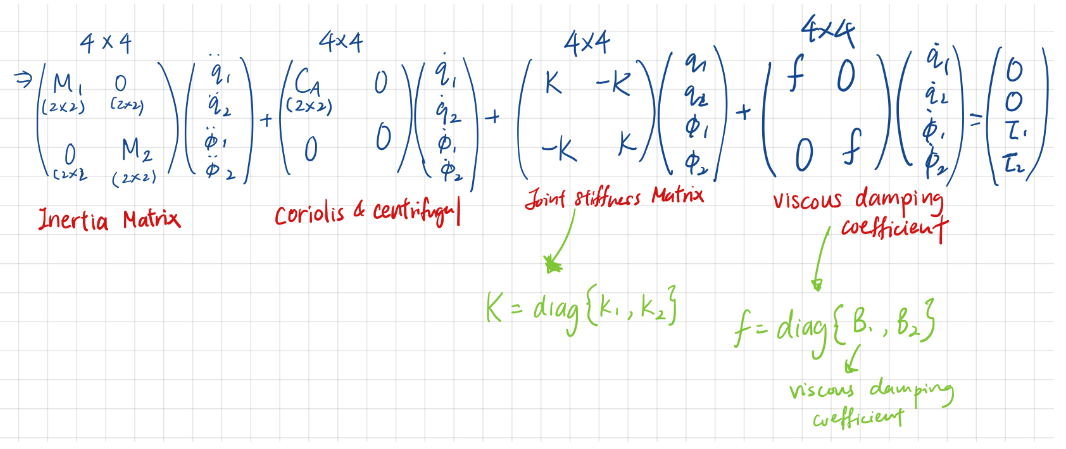

z = [0 0;
     0 0];
M11 = I2+I1+m2*((L1^2)+(Lc2^2)+2*L1*Lc2*cos(q2))+m1*(Lc1^2);
M12 = I2+m2*(Lc2^2)+L1*Lc2*m2*cos(q2);
M21 = M12;
M22 = I2+m2*(Lc2^2);

M1 = [M11 M12;
     M21 M22]

$$M1(t) = \left(\begin{array}{cc} m_{1}\,{{\mathrm{Lc}}_{1}}^{2}+I_{1}+I_{2}+m_{2}\,\left({L_{1}}^{2}+2\,\cos\left(q_{2}\left(t\right)\right)\,L_{1}\,{\mathrm{Lc}}_{2}+{{\mathrm{Lc}}_{2}}^{2}\right) & m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,{\mathrm{Lc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,{\mathrm{Lc}}_{2}+I_{2} & m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+I_{2} \end{array}\right)$$


M2 = [Ir1 0;
      0 Ir2];
  
M = [M1 z;
     z  M2]

$$M(t) = \begin{array}{l} \left(\begin{array}{cccc} m_{1}\,{{\mathrm{Lc}}_{1}}^{2}+I_{1}+I_{2}+m_{2}\,\left({L_{1}}^{2}+2\,\cos\left(q_{2}\left(t\right)\right)\,L_{1}\,{\mathrm{Lc}}_{2}+{{\mathrm{Lc}}_{2}}^{2}\right) & \sigma_{1} & 0 & 0\\ \sigma_{1} & m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+I_{2} & 0 & 0\\ 0 & 0 & {\mathrm{Ir}}_{1} & 0\\ 0 & 0 & 0 & {\mathrm{Ir}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,{\mathrm{Lc}}_{2}+I_{2} \end{array}$$

 
C11 = -m2*L1*Lc2*sin(q2)*diff(q2,t);
C12 = -m2*L1*Lc2*sin(q2)*diff(q2,t)-m2*L1*Lc2*sin(q2)*diff(q1,t);
C21 = m2*L1*Lc2*sin(q2)*diff(q1,t);
C22 = 0;

Ca = [C11 C12;
     C21 C22];

C = [Ca z;
     z  z]

$$C(t) = \left(\begin{array}{cccc} -L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & -L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)-L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & 0 & 0\\ L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

 
K1 = [Ks1 0;
      0  Ks2];
  
K = [K1 -K1;
     -K1 K1]

$$K = \left(\begin{array}{cccc} {\mathrm{Ks}}_{1} & 0 & -{\mathrm{Ks}}_{1} & 0\\ 0 & {\mathrm{Ks}}_{2} & 0 & -{\mathrm{Ks}}_{2}\\ -{\mathrm{Ks}}_{1} & 0 & {\mathrm{Ks}}_{1} & 0\\ 0 & -{\mathrm{Ks}}_{2} & 0 & {\mathrm{Ks}}_{2} \end{array}\right)$$

 
fvl = [B1 0;
      0  B2];
  
fvm = [Bm1 0;
       0  Bm2];
   
fv = [fvl z;
      z  fvm]

$$fv = \left(\begin{array}{cccc} B_{1} & 0 & 0 & 0\\ 0 & B_{2} & 0 & 0\\ 0 & 0 & {\mathrm{Bm}}_{1} & 0\\ 0 & 0 & 0 & {\mathrm{Bm}}_{2} \end{array}\right)$$

  
acce=[Q1DD;Q2DD;PHI1DD;PHI2DD]

$$acce = \left(\begin{array}{c} \mathrm{Q1DD}\\ \mathrm{Q2DD}\\ \mathrm{PHI1DD}\\ \mathrm{PHI2DD} \end{array}\right)$$

vel = [Q1D;Q2D;PHI1D;PHI2D]

$$vel = \left(\begin{array}{c} \mathrm{Q1D}\\ \mathrm{Q2D}\\ \mathrm{PHI1D}\\ \mathrm{PHI2D} \end{array}\right)$$

pos = [Q1;Q2;PHI1;PHI2]

$$pos = \left(\begin{array}{c} Q_{1}\\ Q_{2}\\ {\mathrm{PHI}}_{1}\\ {\mathrm{PHI}}_{2} \end{array}\right)$$

syms tau1 tau2
eqn = [0;0;tau1;tau2]

$$eqn = \left(\begin{array}{c} 0\\ 0\\ \tau_{1}\\ \tau_{2} \end{array}\right)$$


M = subs(M,actual,holder)

$$M(t) = \left(\begin{array}{cccc} m_{1}\,{{\mathrm{Lc}}_{1}}^{2}+I_{1}+I_{2}+m_{2}\,\left({L_{1}}^{2}+2\,\cos\left(Q_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}+{{\mathrm{Lc}}_{2}}^{2}\right) & m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(Q_{2}\right)\,{\mathrm{Lc}}_{2}+I_{2} & 0 & 0\\ m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(Q_{2}\right)\,{\mathrm{Lc}}_{2}+I_{2} & m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+I_{2} & 0 & 0\\ 0 & 0 & {\mathrm{Ir}}_{1} & 0\\ 0 & 0 & 0 & {\mathrm{Ir}}_{2} \end{array}\right)$$

C = subs(C,actual,holder)

$$C(t) = \left(\begin{array}{cccc} -L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q2D}\,m_{2}\,\sin\left(Q_{2}\right) & -L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q1D}\,m_{2}\,\sin\left(Q_{2}\right)-L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q2D}\,m_{2}\,\sin\left(Q_{2}\right) & 0 & 0\\ L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q1D}\,m_{2}\,\sin\left(Q_{2}\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

K = subs(K,actual,holder)

$$K = \left(\begin{array}{cccc} {\mathrm{Ks}}_{1} & 0 & -{\mathrm{Ks}}_{1} & 0\\ 0 & {\mathrm{Ks}}_{2} & 0 & -{\mathrm{Ks}}_{2}\\ -{\mathrm{Ks}}_{1} & 0 & {\mathrm{Ks}}_{1} & 0\\ 0 & -{\mathrm{Ks}}_{2} & 0 & {\mathrm{Ks}}_{2} \end{array}\right)$$

fv = subs(fv,actual,holder)

$$fv = \left(\begin{array}{cccc} B_{1} & 0 & 0 & 0\\ 0 & B_{2} & 0 & 0\\ 0 & 0 & {\mathrm{Bm}}_{1} & 0\\ 0 & 0 & 0 & {\mathrm{Bm}}_{2} \end{array}\right)$$


eqn1= M*acce+C*vel+K*pos+fv*vel==eqn

$$eqn1(t) = \begin{array}{l} \left(\begin{array}{c} \mathrm{Q1DD}\,\left(m_{1}\,{{\mathrm{Lc}}_{1}}^{2}+I_{1}+I_{2}+m_{2}\,\left({L_{1}}^{2}+2\,\cos\left(Q_{2}\right)\,L_{1}\,{\mathrm{Lc}}_{2}+{{\mathrm{Lc}}_{2}}^{2}\right)\right)-\mathrm{Q2D}\,\left(L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q1D}\,m_{2}\,\sin\left(Q_{2}\right)+L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q2D}\,m_{2}\,\sin\left(Q_{2}\right)\right)+\mathrm{Q2DD}\,\sigma_{1}+B_{1}\,\mathrm{Q1D}-{\mathrm{Ks}}_{1}\,{\mathrm{PHI}}_{1}+{\mathrm{Ks}}_{1}\,Q_{1}-L_{1}\,{\mathrm{Lc}}_{2}\,\mathrm{Q1D}\,\mathrm{Q2D}\,m_{2}\,\sin\left(Q_{2}\right)=0\\ L_{1}\,{\mathrm{Lc}}_{2}\,m_{2}\,\sin\left(Q_{2}\right)\,{\mathrm{Q1D}}^{2}+\mathrm{Q2DD}\,\left(m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+I_{2}\right)+\mathrm{Q1DD}\,\sigma_{1}+B_{2}\,\mathrm{Q2D}-{\mathrm{Ks}}_{2}\,{\mathrm{PHI}}_{2}+{\mathrm{Ks}}_{2}\,Q_{2}=0\\ {\mathrm{Bm}}_{1}\,\mathrm{PHI1D}+{\mathrm{Ir}}_{1}\,\mathrm{PHI1DD}+{\mathrm{Ks}}_{1}\,{\mathrm{PHI}}_{1}-{\mathrm{Ks}}_{1}\,Q_{1}=\tau_{1}\\ {\mathrm{Bm}}_{2}\,\mathrm{PHI2D}+{\mathrm{Ir}}_{2}\,\mathrm{PHI2DD}+{\mathrm{Ks}}_{2}\,{\mathrm{PHI}}_{2}-{\mathrm{Ks}}_{2}\,Q_{2}=\tau_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{{\mathrm{Lc}}_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(Q_{2}\right)\,{\mathrm{Lc}}_{2}+I_{2} \end{array}$$